## Udregning af akustisk frekvenskarakteristik

**Model for lukket kabinet:**

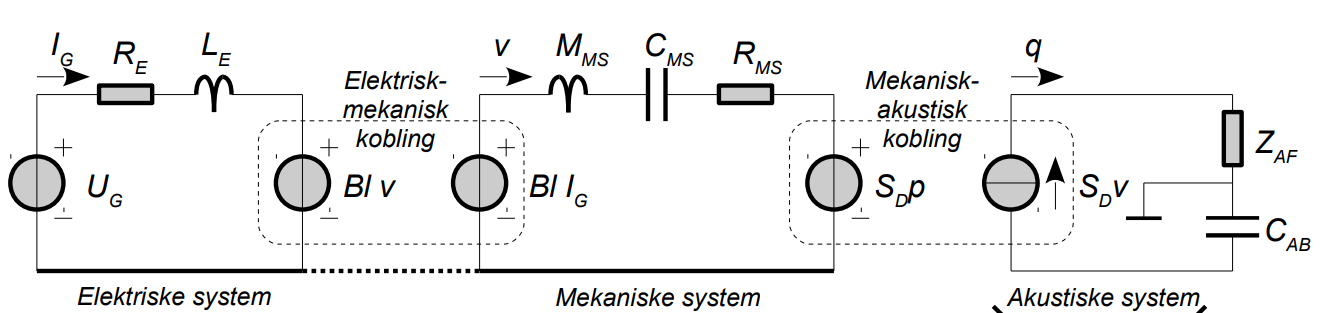

**Model for bass-reflex**

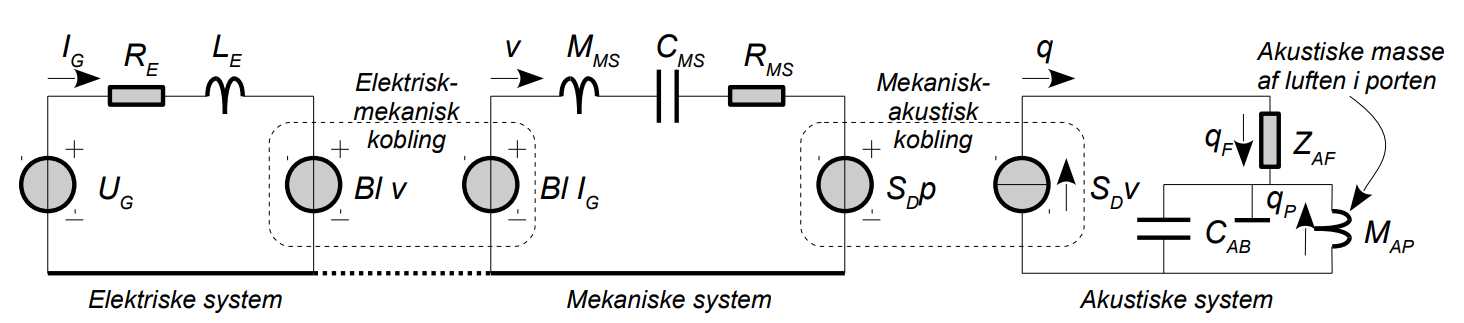

**Ækvivalent load (lukket forside - 4th order):**

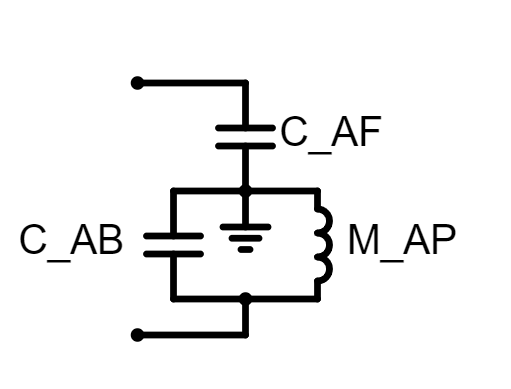

#### Ækvivalent load (ported forside - 6th order)

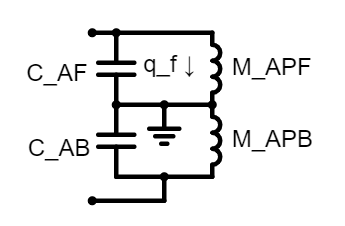

#### Højtalerparametre:

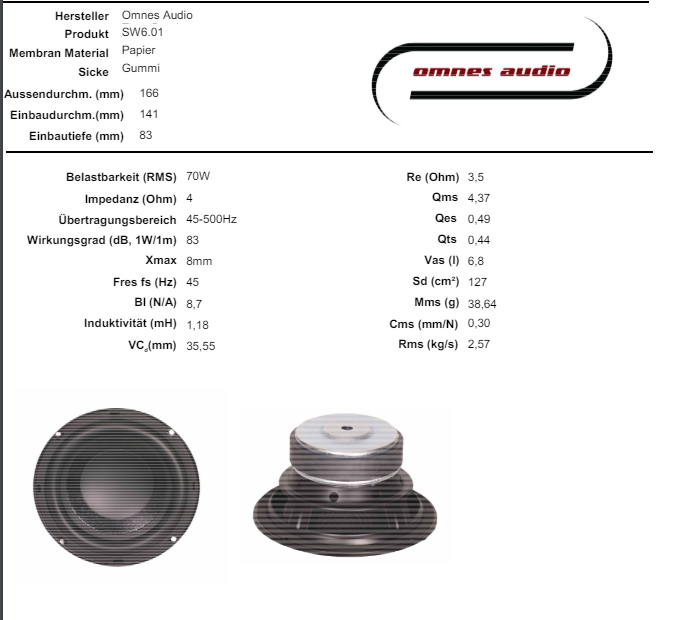

#### Elektrisk:


ts.Re = 3.5; % Ohm
ts.Le = 1.18e-3; % H
ts.Bl = 8.7; % N/A

#### Mekanisk:

ts.Mms = 38.64e-3; % kg
ts.Cms = 0.3e-3; % m/N
ts.Rms = 2.57; % kg/s
ts.Sd = 127e-4 % 127cm^2 in m^2

ts = struct with fields:
     Re: 3.5000
     Le: 0.0012
     Bl: 8.7000
    Mms: 0.0386
    Cms: 3.0000e-04
    Rms: 2.5700
     Sd: 0.0127


#### Akustisk:

% TODO - find en passende strålingsimpedans
Zaf_val = 1;
Zab_val = 1;

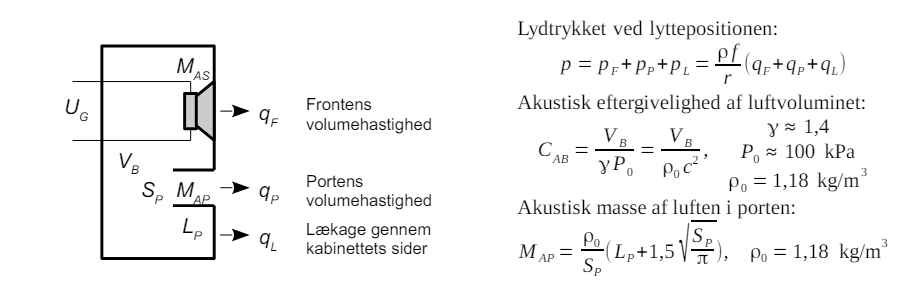

c = 343; % m/s
rho0 = 1.18; % kg/m^3
back_box_volume = 60e-3; % 60 liters in m^3
back_port_len = 30e-2; % 30 cm in m

$$I\_G = \frac{U_{G}}{\left(\frac{{\mathrm{Bl}}^{2}\,\mathrm{Cms}\,s}{\left(\Re+\mathrm{Le}\,s\right)\,\left(\mathrm{Cms}\,\mathrm{Rms}\,s+\mathrm{Cms}\,\mathrm{Mms}\,s^{2}+\mathrm{Cms}\,{\mathrm{Sd}}^{2}\,\mathrm{Zab}\,s+\mathrm{Cms}\,{\mathrm{Sd}}^{2}\,\mathrm{Zaf}\,s+1\right)}+1\right)\,\left(\Re+\mathrm{Le}\,s\right)}$$

back_port_diameter = 10e-2; % 10 cm in m
back_port_s_p = pi*(back_port_diameter/2)^2;
back_C_AB = back_box_volume/(rho0*c^2)
back_M_AP = rho0/back_port_s_p * (back_port_len+1.5*sqrt(back_port_s_p/pi))
front_box_volume = 10e-3; % 10 liters in m^3
front_port_len = 10e-2; % 10 cm in m
front_port_diameter = 10e-2; % 10 cm in m

#### Overføringsfunktion elektrisk:

Der regnes fra højre i diagrammet mod venstre for at afkoble kredsløbene (kredsløbet ses fra den elektriske sidde).

Superposition mellem kilderne bruges i hver "loop" for at finde "strøm"-bidrag.

"Solve" bruges da udtrykkene bliver meget lange og da eksempeltvis $v$ og $I_G$ kommer til at stå på begge sider af lighedstegnet.

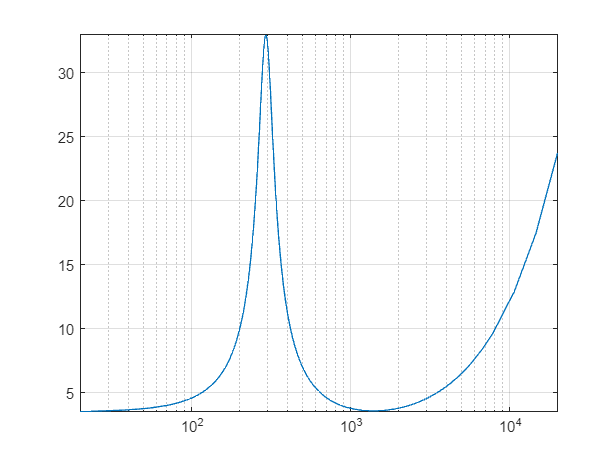

syms I_G U_G Bl Re s Le Sd p Mms Cms Rms v Zab Zaf
p = Sd*v*Zab + Sd*v*Zaf;
v = simplify(solve(v == (Bl*I_G)/(s*Mms + 1/(s*Cms) + Rms) - (Sd * p)/(s*Mms + 1/(s*Cms) + Rms), v));
I_G = simplify(solve(I_G == U_G/(Re + s*Le) - (Bl*v)/(Re + s*Le), I_G))

Læg mærke til $p$ og $v$ nu er koblet af udtrykket for $I_G$. Nu kan $H_Z \left(s\right)=\frac{U_G \left(s\right)}{I_G \left(s\right)}$ findes.

H_Z(s) = simplify(U_G/I_G);
H_Z(s) = simplify(subs(H_Z(s), [Re, Le, Bl, Mms, Cms, Rms, Sd, Zaf, Zab], [ts.Re, ts.Le, ts.Bl, ts.Mms, ts.Cms, ts.Rms, ts.Sd, Zaf_val, Zab_val]));
figure(2)
syms omega

$$p = \frac{\mathrm{Bl}\,\mathrm{Cms}\,\mathrm{Sd}\,U_{G}\,s\,\left(\mathrm{Zab}+\mathrm{Zaf}\right)}{\Re+\mathrm{Le}\,s+{\mathrm{Bl}}^{2}\,\mathrm{Cms}\,s+\mathrm{Cms}\,\mathrm{Le}\,\mathrm{Mms}\,s^{3}+\mathrm{Cms}\,\mathrm{Le}\,\mathrm{Rms}\,s^{2}+\mathrm{Cms}\,\mathrm{Mms}\,\Re\,s^{2}+\mathrm{Cms}\,\Re\,\mathrm{Rms}\,s+\mathrm{Cms}\,\Re\,{\mathrm{Sd}}^{2}\,\mathrm{Zab}\,s+\mathrm{Cms}\,\Re\,{\mathrm{Sd}}^{2}\,\mathrm{Zaf}\,s+\mathrm{Cms}\,\mathrm{Le}\,{\mathrm{Sd}}^{2}\,\mathrm{Zab}\,s^{2}+\mathrm{Cms}\,\mathrm{Le}\,{\mathrm{Sd}}^{2}\,\mathrm{Zaf}\,s^{2}}$$

plt = fplot(abs(H_Z(1j*omega)));
g = gca;
g.XScale = "log";
g.YScale ="linear";
xlim([20, 20e3])
grid on

#### Overføringsfunktion Akustisk:

Der regnes fra venstre i diagrammet mod højre for at afkoble kredsløbene (kredsløbet ses fra den akustiske side).

Fremgangsmåden er den samme som for overførselsfunktion for den elektriske impedans.

syms I_G U_G Bl Re s Le Sd p Mms Cms Rms v Zab Zaf
I_G = simplify(solve(I_G == U_G/(Re + s*Le) - (Bl*v)/(Re + s*Le), I_G));
v = simplify(solve(v == (Bl*I_G)/(s*Mms + 1/(s*Cms) + Rms) - (Sd * p)/(s*Mms + 1/(s*Cms) + Rms), v));
p = simplify(solve(p == Sd*v*Zab + Sd*v*Zaf, p))

Læg mærke til $I_G$ og $v$ nu er koblet af udtrykket for $p$. Nu kan $H_p \left(s\right)=\frac{p\left(s\right)}{U_G \left(s\right)}$ findes.

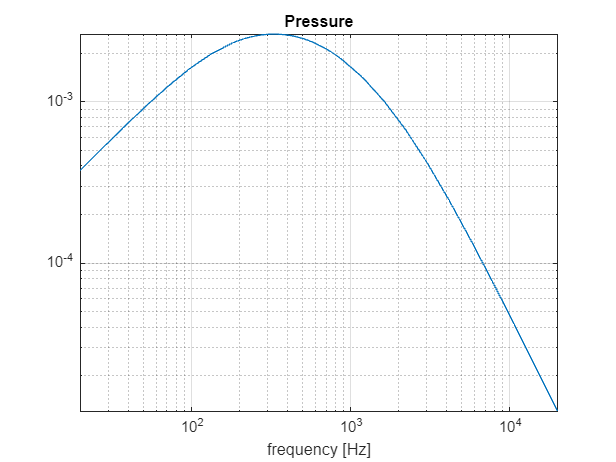

H_P(s) = simplify(p/U_G);
H_P(s) = simplify(subs(H_P(s), [Re, Le, Bl, Mms, Cms, Rms, Sd, Zaf, Zab], [ts.Re, ts.Le, ts.Bl, ts.Mms, ts.Cms, ts.Rms, ts.Sd, Zaf_val, Zab_val]));
figure(2)

syms omega
plt = fplot(abs(H_P(1j*omega)));
g = gca;
g.XScale = "log";
g.YScale ="log";
xlim([20, 20e3])
grid on
title("Pressure")
xlabel("frequency [Hz]")